Sy=400;  %Esfuerzo fluencia
Sut=520; %Esfuerzo último
Sm=0.9*Sut

Sm = 468


%Esfuerzos principales (MPa)
sigmaP1=86.4;
sigmaP2=0;
sigmaP3=0;

N=5*10^4; %número de ciclos
N2=10^6; %articulación de rodilla
N1=10^3; %Empieza alto ciclaje

sigmaA=0.5.*(sigmaP1-sigmaP3);   %esfuerzo alternante
sigmaM=0.5.*(sigmaP1+sigmaP3);   %esfuerzo medio


if(Sut<1378.95)
    SeInicial=0.5.*Sut;
else
    SeInicial=689.476;
end


%Factores de corrección
Ccar=1

Ccar = 1

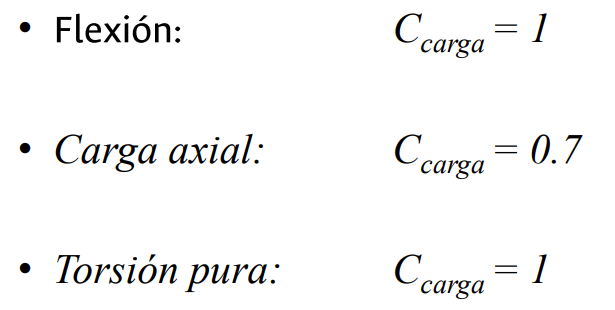

Ctam=0.868

Ctam = 0.8680

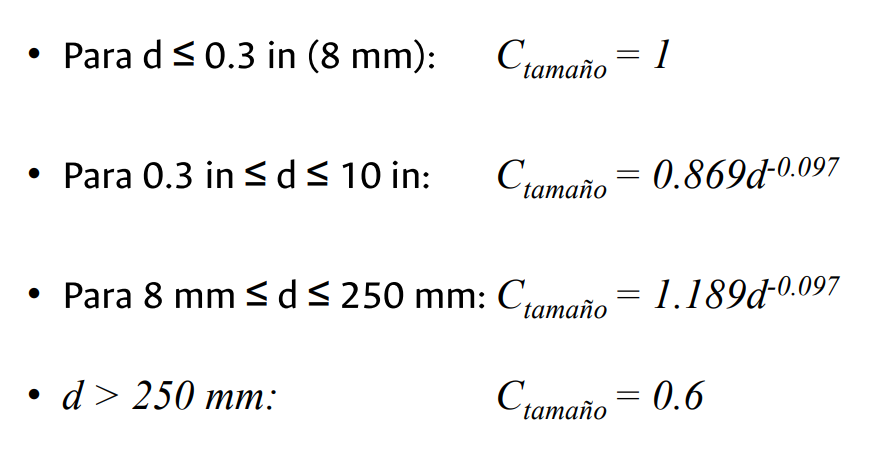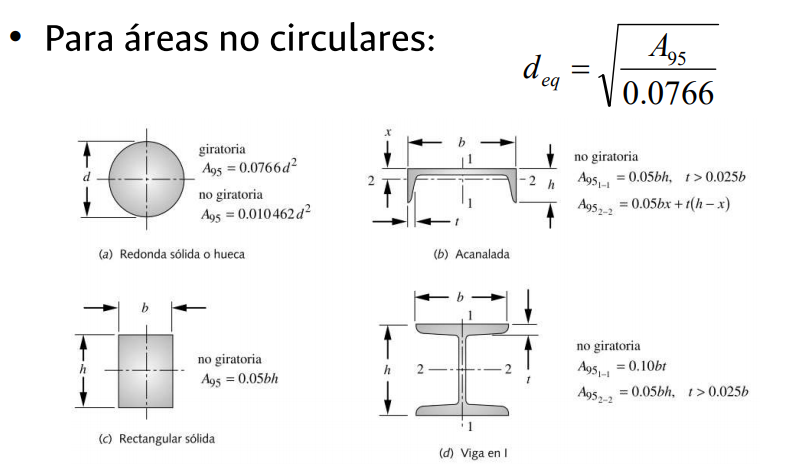

Csup=0.86

Csup = 0.8600

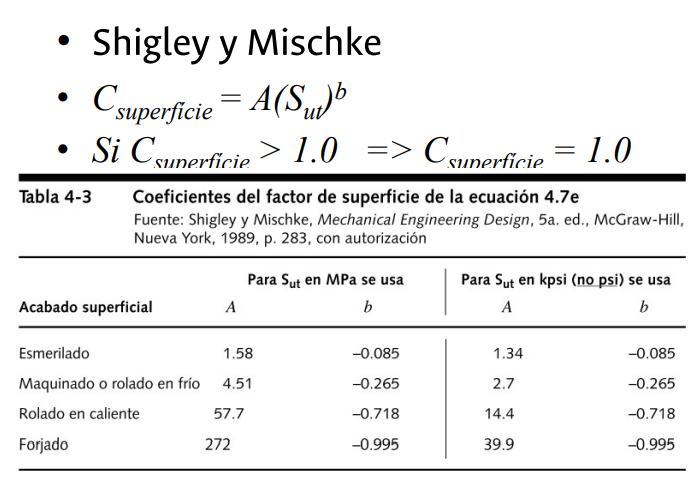

Ctem=1

Ctem = 1

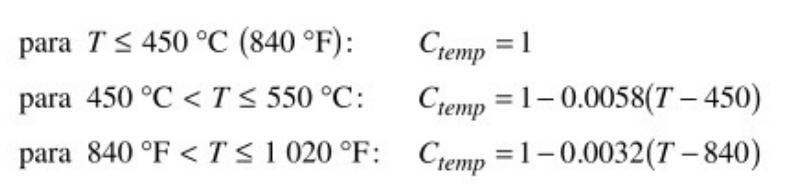

Ccon=0.897

Ccon = 0.8970

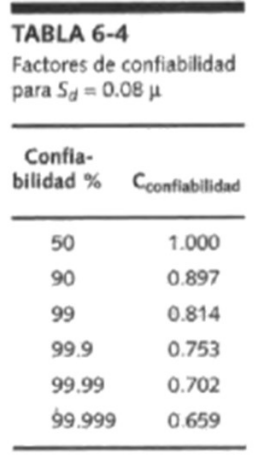


SeFinal=SeInicial*Ccar*Ctam*Csup*Ctem*Ccon

SeFinal = 174.0941

z=log10(N1)-log10(N2);
b=z.^-1.*log10(Sm/SeFinal);
a=10.^(log10(Sm)-b.*log10(N1));
Sf=a*N^b;


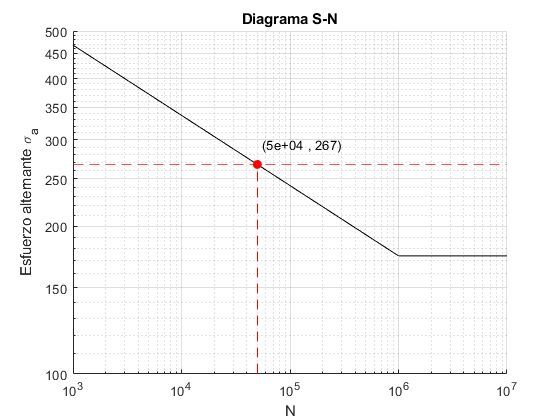


arrayN=logspace(3,7,1000);
f=a*arrayN.^b.*(arrayN<10^6);
C=SeFinal*(arrayN>10^6);
hold on
loglog(arrayN,f,"k")
plot(arrayN,C,"k")
stem(N,Sf,"filled","r--o")
text(1.1*N,1.1*Sf,sprintf('(%.0e , %.0f)', N,Sf))
hold off
set(gca, 'XScale', 'log')
set(gca, 'YScale', 'log')
grid on
xlim([10^3 10^7])
ylim([100 500])
yline(Sf,"r--")
title("Diagrama S-N")
xlabel("N")
ylabel("Esfuerzo alternante \sigma_{a}")


syms x1 x2
lineaF=@(x)    Sy-x;
goodManM=@(x)   Sf-x/Sut.*Sf;
lineaC=@(x)     sigmaA.*x./sigmaM;
Fr=sigmaA.*x1/sigmaM==Sf-x1./Sut.*Sf;
Fq= Sy-x2==sigmaA;


FSm=double(solve(Fr,x1))

FSm = 176.5564

FSy=double(solve(Fq,x2))

FSy = 356.8000

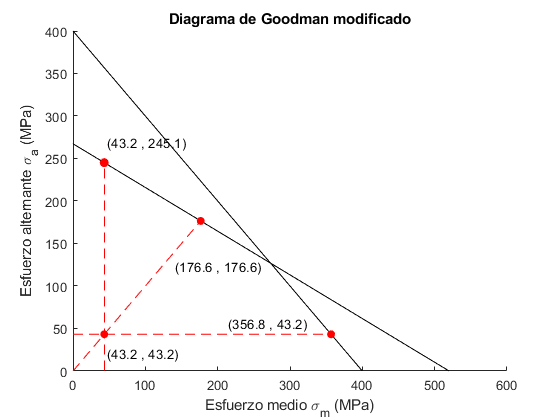


scatter(sigmaM,sigmaA,"r","filled")
hold on
fplot(lineaF,[0 Sy],"k")
fplot(goodManM,[0 Sut],"k")
fplot(lineaC,[0 FSm],"r--")
stem(sigmaM,goodManM(sigmaM),"r--","filled")
scatter(FSm,goodManM(FSm),"r","filled")
scatter(FSy,sigmaA,"r","filled")
fplot(sigmaA,[0 FSy],"r--")
scatter(sigmaM,sigmaA,"r","filled")
text(1.1*sigmaM,0.5*sigmaA,sprintf('(%.1f , %.1f)', sigmaM,sigmaA))
text(1.1*sigmaM,1.1*goodManM(sigmaM),sprintf('(%.1f , %.1f)', sigmaM,goodManM(sigmaM)))
text(0.8*FSm,0.7*goodManM(FSm),sprintf('(%.1f , %.1f)', FSm,goodManM(FSm)))
text(0.6*FSy,1.3*sigmaA,sprintf('(%.1f , %.1f)', FSy,sigmaA))
hold off
title("Diagrama de Goodman modificado")
xlabel("Esfuerzo medio \sigma_m (MPa)")
ylabel("Esfuerzo alternante \sigma_a (MPa)")



FS1=goodManM(sigmaM)/sigmaA

FS1 = 5.6739

FS2=sqrt(FSm^2+goodManM(FSm)^2)/sqrt(sigmaM^2+sigmaA^2)

FS2 = 4.0870

FS3=FSy/sigmaM

FS3 = 8.2593

FS=min([FS1 FS2 FS3])

FS = 4.0870